% Cleanup!
clear all 
close all
clc

start_trim = 73

start_trim = 73

time_length = 60

time_length = 60


[MotionData]=ParseMatlabApp('7min_nathan_50hz_normal.mat')

MotionData = struct with fields:
            Accel: [24129×3 double]
      Orientation: [24129×3 double]
           AngVel: [24128×3 double]
          t_Accel: [24129×1 double]
    t_Orientation: [24129×1 double]
         t_AngVel: [24128×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556


MotionData.t_Accel(end)

ans = 434.3040

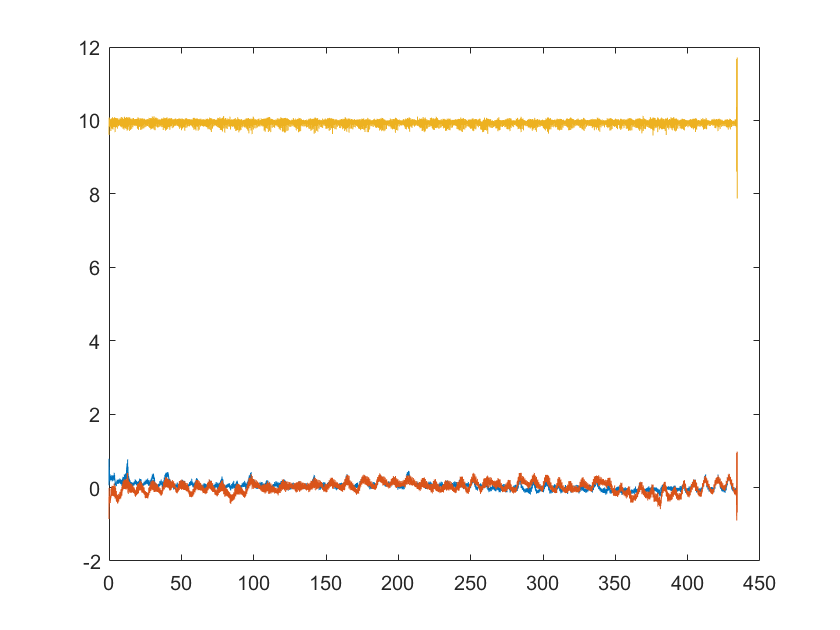

plot(MotionData.t_Accel, MotionData.Accel)

[chunked_t_Accel,chunked_Accel] = TrimMotionData(MotionData,time_length,start_trim)

Fs = 55.5556

N = 24129

chunk_sz = 60

chunks = 10

chunk_sz_index = 3333

front_trim = 73

index_front = 4057

MotionData = struct with fields:
            Accel: [24129×3 double]
      Orientation: [24129×3 double]
           AngVel: [24128×3 double]
          t_Accel: [20073×1 double]
    t_Orientation: [24129×1 double]
         t_AngVel: [24128×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556



chunked_Accel =

  0×0 empty cell array


chunked_t_Accel =

  0×0 empty cell array



chunked_t_Accel = 1×21 cell array
    {3333×1 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×1 double}


chunked_Accel = 1×21 cell array
    {3333×3 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×3 double}


%MotionData.t_Accel = MotionData.t_Accel(index_front:index_end)-MotionData.t_Accel(1)
N = length(chunked_t_Accel{1})

N = 3333

Fs = MotionData.accel_rate % in hertz

Fs = 55.5556

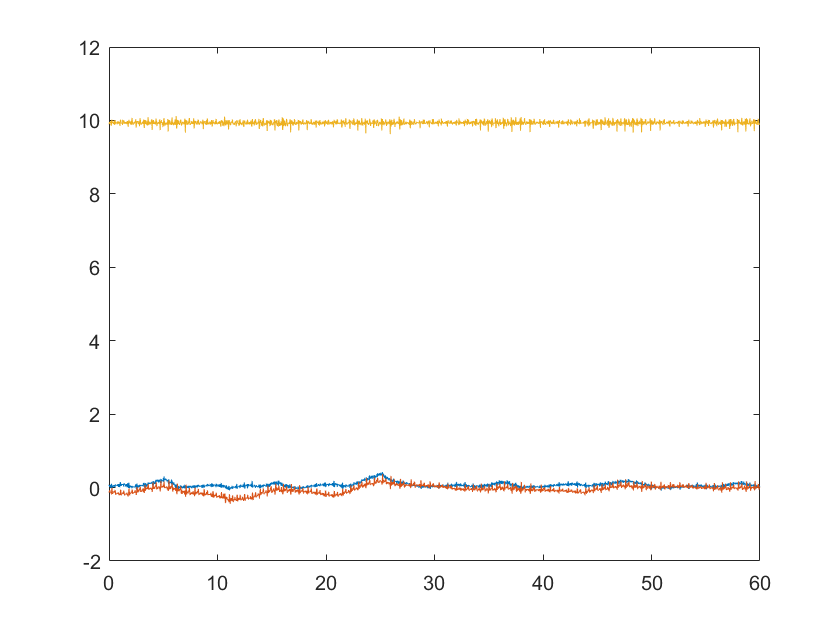

plot(chunked_t_Accel{1}, chunked_Accel{1})

%Load Control Data
[ContData]=ParseMatlabApp('10min_control_50hz.mat')

ContData = struct with fields:
            Accel: [31900×3 double]
      Orientation: [31897×3 double]
           AngVel: [31897×3 double]
          t_Accel: [31900×1 double]
    t_Orientation: [31897×1 double]
         t_AngVel: [31897×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556


[chunked_t,chunked_C_Accel] = TrimMotionData(ContData,time_length,start_trim)

Fs = 55.5556

N = 31900

chunk_sz = 60

chunks = 10

chunk_sz_index = 3333

front_trim = 3

index_front = 168

MotionData = struct with fields:
            Accel: [31900×3 double]
      Orientation: [31897×3 double]
           AngVel: [31897×3 double]
          t_Accel: [31733×1 double]
    t_Orientation: [31897×1 double]
         t_AngVel: [31897×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556



chunked_Accel =

  0×0 empty cell array


chunked_t_Accel =

  0×0 empty cell array



chunked_t = 1×45 cell array
    {3333×1 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×1 double}


chunked_C_Accel = 1×45 cell array
    {3333×3 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×3 double}


%MotionData.t_Accel = MotionData.t_Accel(index_front:index_end)-MotionData.t_Accel(1)
N = length(chunked_t{1});
Fs = MotionData.accel_rate % in hertz

Fs = 55.5556

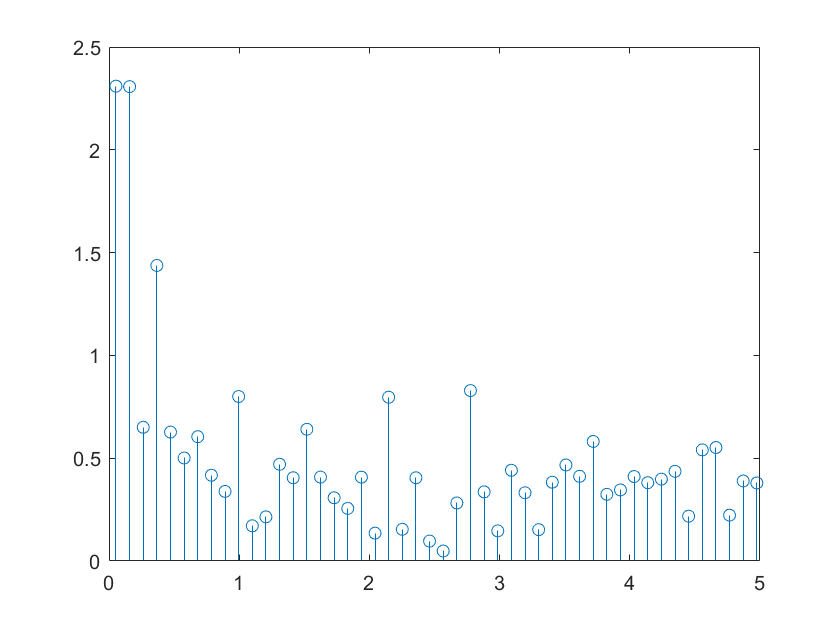

contrldata = chunked_C_Accel{1};
y_fft = fft(contrldata(:, 3));
y_fft_shift2 = abs(fftshift(y_fft));
frequencies_shifted2 = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
figure(1)
stem(frequencies_shifted2,y_fft_shift2)
xlim([0 5])

data = chunked_Accel{1}

data =     0.3162   -0.1216    9.8589
    0.2491   -0.1072    9.9526
    0.2479   -0.1048    9.9056
    0.3078   -0.0877    9.8326
    0.2707   -0.0734    9.9850
    0.2264   -0.0650   10.0272
    0.3354    0.0320   10.0595
    0.3294   -0.0003    9.9970
    0.2623   -0.1144    9.9263
    0.2731   -0.1671    9.8709


y_fft = fft(data(:, 3));
y_fft_shift = abs(fftshift(y_fft))-y_fft_shift2;
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

breath_low = 8/60

breath_low = 0.1333

breath_high = 20/60

breath_high = 0.3333

hb_low = 40/60

hb_low = 0.6667

hb_high = 100/60

hb_high = 1.6667


filter_inds = breath_high <= frequencies_shifted & frequencies_shifted <= hb_low | hb_high <= frequencies_shifted | frequencies_shifted <= breath_low;
y_fft_shift(filter_inds) = y_fft_shift(filter_inds)/10;

filter_inds = find(frequencies_shifted == 0)


filter_inds =

  1×0 empty double row vector



y_fft_shift(filter_inds) = 0

y_fft_shift = 	1.0e+03 *

   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0000
   -0.0000
    0.0001
   -0.0000
    0.0000


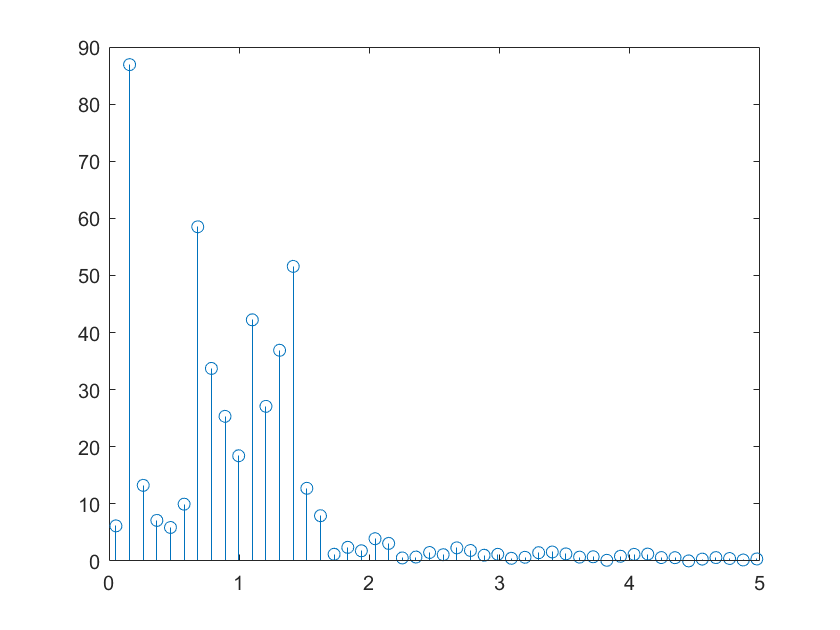


figure(2)
stem(frequencies_shifted, y_fft_shift)
xlim([0 5])